# MPU6050 - Analyse en déplacement - Donnée DMP

Ce fichier présente les caractéristiques de IMU MPU6050 en mode DMP et du magnetomètre HMC5883L pendnt un déplacement

Le fichier 'DATA*.TXT' contient les lectures de l'accéléromètre et gyroscope de IMU MPU6050 en mode DMP et du magnetomètre HMC5883L pendant une periode ou un l'on retrouve divers déplacement. 

Le fichier de donné à la stracuture suivante pour chaque lecture.

`dt:0.0350                     `est le delta entre la dernière lecture et la présente

`accel:6,-6,8207               `valeur d'accélération brute obtenu à travers une lecture de l'accéléromètre en mode DMP

`laccel:1,-4,14                `accélération linéaire est l'ensemble des vecteurs (x,y,z) d'accélération brute moin le vecteur d'accélération gravitationel extrait du quaternion.

`laccelw:1,3,14                `accélération linéaire en référentiel terrestre est  l'ensemble des vecteurs (x,y,z) 

                              d'accélération linéaire après une rotation selon l'orientation du quaternion.

`g:0.00,-0.00,1.00             `le vecteur d'accélération gravitationel extrait du quaternion.

`gyro:0,-1,0                   `valeur du gyroscope brute en mode DMP 

`mag:-152.23,189.50,-426.12    `valeur du gyroscope brute 

`q:-0.26,-0.00,0.00,-0.96      `valeur du quaternion obtenu à travers une lecture du DMP

`heading:141.38                `la direction en º, à partir des valeurs du magétomètre.

`TotalTime:80.0278             `les valeurs ci-dessus on été obtenu à ce moment *t*

## Chargement des données brutes

close all;                    % fermeture de tous les figures
clear;                        % effacer tous les variables
clc;                       % effacer tous les commndes du terminal

[ accel, laccel, laccelw, g, rawGyro, rawMag, Q, heading, avgDt, totalTime] = loadDMPSensorsData('DATA_Y_60secs_up.TXT');

## Auto Calibration du Digital Motion Processor (DMP)

Nous avons observé une période d'auto-calibration pendant les premières secondes de lecture de donnée du capteur MPU6050 en mode Digital Motion Processor (DMP).

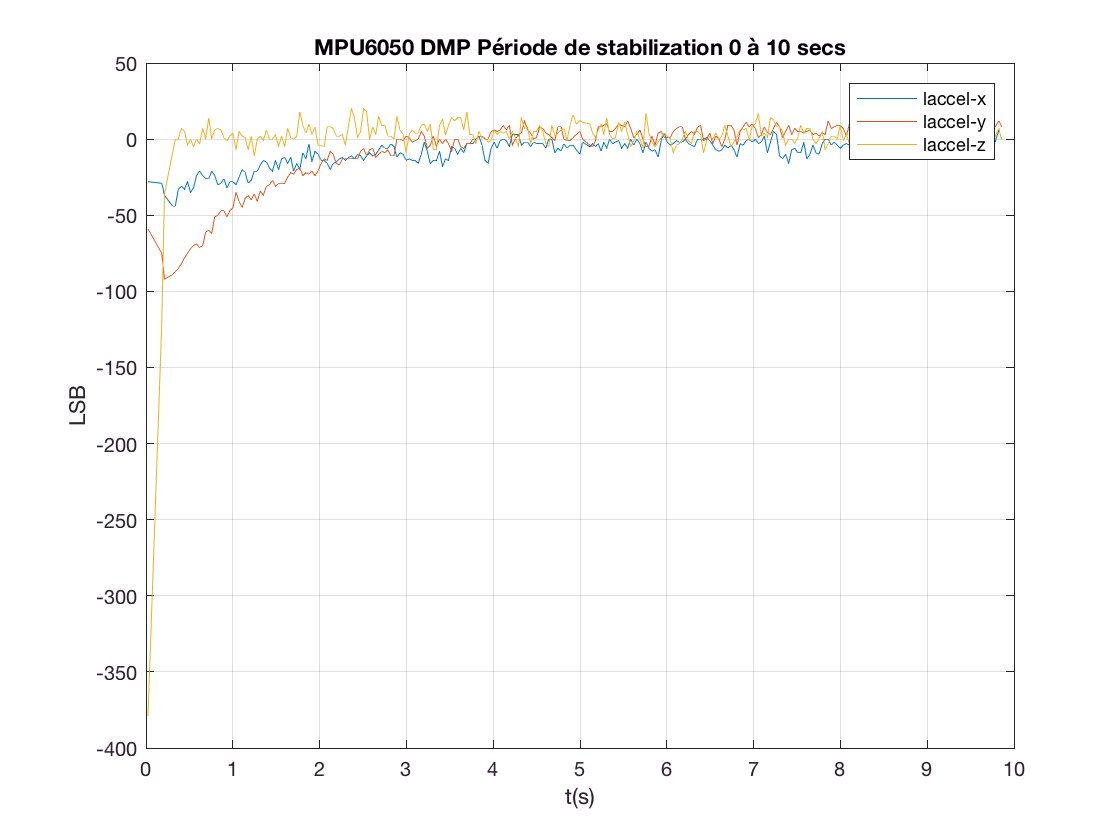

idx10 = int32(10.0 / avgDt);
figure
plot(laccel(1:idx10,4), laccel(1:idx10,1), laccel(1:idx10,4), laccel(1:idx10,2), laccel(1:idx10,4), laccel(1:idx10,3));
title 'MPU6050 DMP Période de stabilization 0 à 10 secs';
legend({'laccel-x' 'laccel-y' 'laccel-z'});
grid 'on';
ylabel 'LSB';
xlabel 't(s)';

Il semble qu'après 30 secondes, le capteurs soit stabilisé. Alors, nous allons concentrer notres analyse des données une fois 30 secondes écoulés.

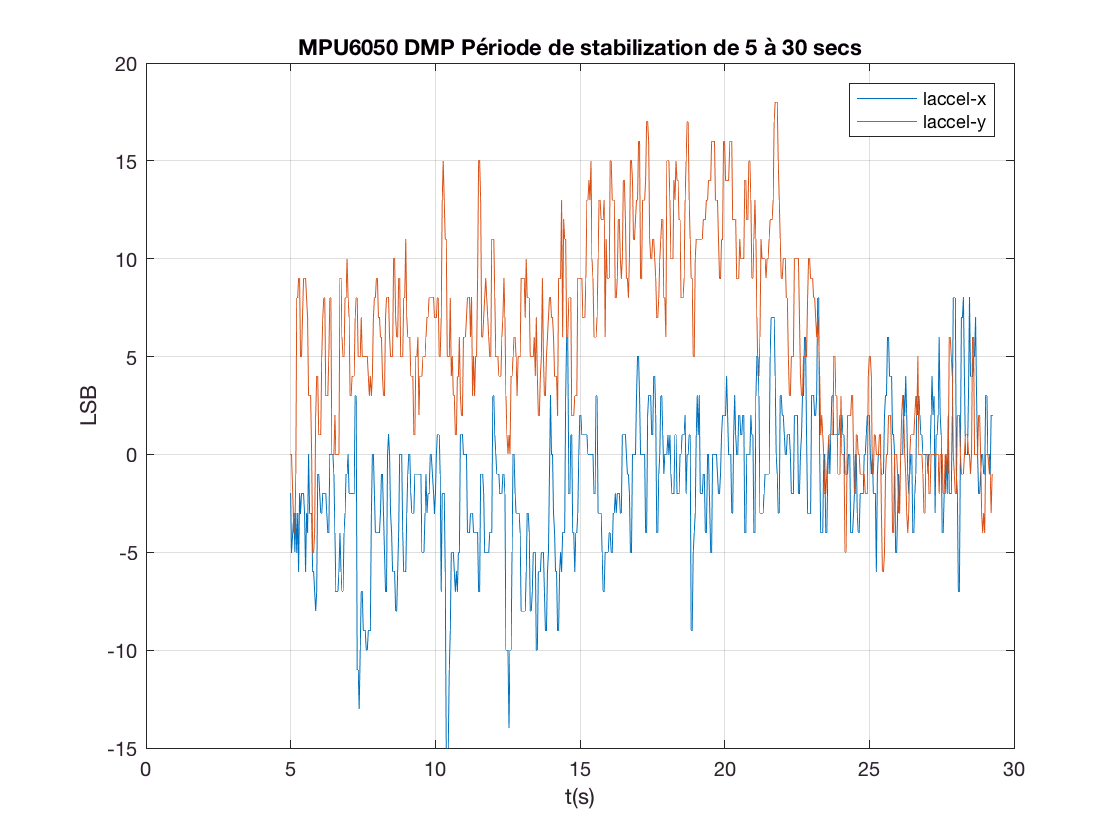

idx5 = int32(5.0 / avgDt);
idx60 = int32(30.0 / avgDt);
figure
plot( laccel(idx5:idx60,4), medfilt1(laccel(idx5:idx60,1), 3), laccel(idx5:idx60,4), medfilt1(laccel(idx5:idx60,2), 3));
title 'MPU6050 DMP Période de stabilization de 5 à 30 secs';
legend({'laccel-x' 'laccel-y'});
grid 'on';
ylabel 'LSB';
xlabel 't(s)';

Nous prennons un sous ensemble des données aprés aproximativement 30 secondes d'écoulées.

indexApresStab = int32(30.0 / avgDt);

sub_timestamp = accel(indexApresStab+1:end,4);
sub_accel = accel(indexApresStab+1:end,:);
sub_laccel = laccel(indexApresStab+1:end,:);
sub_laccelw = laccelw(indexApresStab+1:end,:);
sub_rawGyro = rawGyro(indexApresStab+1:end,:);
sub_rawMag = rawMag(indexApresStab+1:end,:);
sub_Q = Q(indexApresStab+1:end,:);
sub_g = g(indexApresStab+1:end,:);
sub_heading = heading(indexApresStab+1:end,:);


# Comparaisons des trois (3) différentes lecture de l'accéléromètre offertent par le pilote MPU6050 en mode DMP.

## Compariason pour l'axe des X

accel : l'ensemble de vecteur (x,y,z) d'accélération brute obtenu à travers des lectures de l'accéléromètre en mode DMP.

laccel : l'ensemble de vecteur (x,y,z) d'accélération linéaire est l'ensemble des vecteurs (x,y,z) d'accélération brute moin le vecteur d'accélération gravitationel extrait du quaternion.

laccelw : l'ensemble de vecteur (x,y,z) d'accélération linéaire en référentiel terrestre est  l'ensemble des vecteurs (x,y,z) d'accélération linéaire après une rotation selon l'orientation du quaternion.

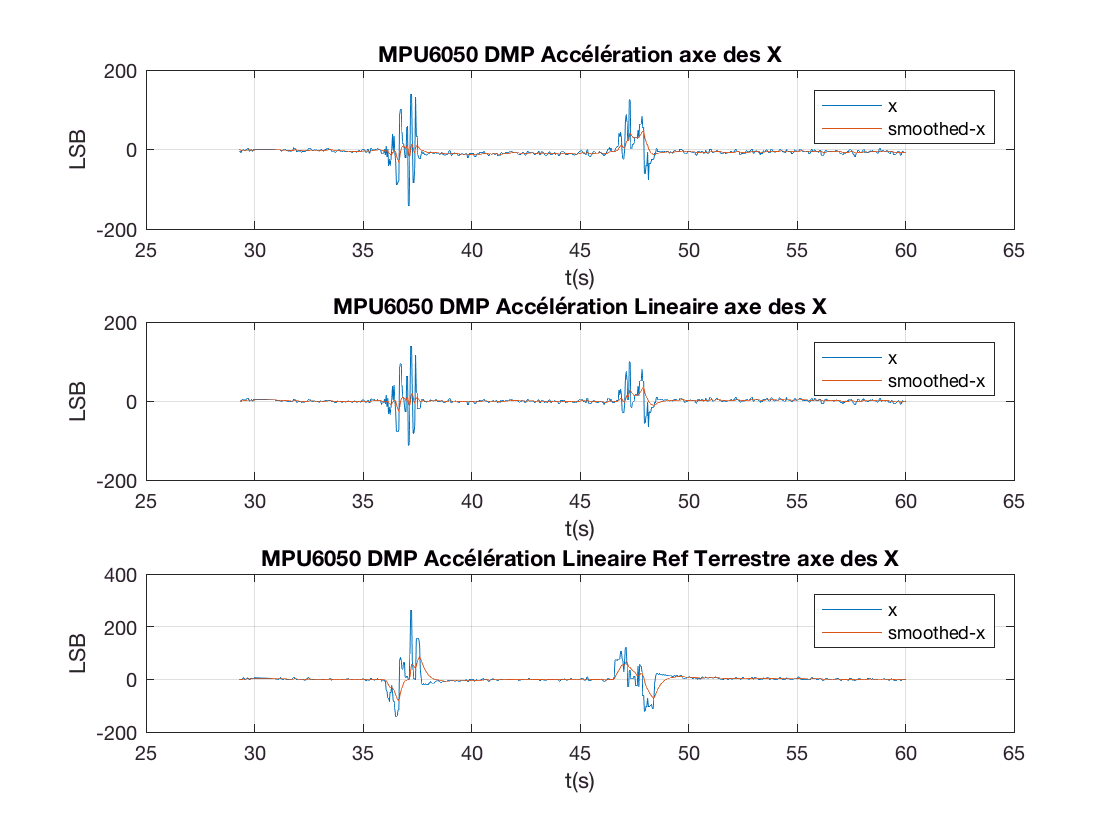

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), medfilt1(sub_accel(:,1), 3), sub_timestamp(:), EMA(medfilt1(sub_accel(:,1),3), 0.1, 0.0));
str = ['MPU6050 DMP Accélération axe des X'];
title(ax1,str);
legend(ax1, {'x' 'smoothed-x'});
grid(ax1, 'on');
ylabel(ax1,'LSB');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), medfilt1(sub_laccel(:,1),3), sub_timestamp(:), EMA(medfilt1(sub_laccel(:,1),3), 0.1, 0.0));
str = ['MPU6050 DMP Accélération Lineaire axe des X'];
title(ax2,str);
legend(ax2, {'x' 'smoothed-x'});
grid(ax2, 'on');
ylabel(ax2,'LSB');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), medfilt1(sub_laccelw(:,1),3), sub_timestamp(:), EMA(medfilt1(sub_laccelw(:,1),3), 0.1, 0.0));
str = ['MPU6050 DMP Accélération Lineaire Ref Terrestre axe des X'];
title(ax3,str);
legend(ax3, {'x' 'smoothed-x'});
grid(ax3, 'on');
ylabel(ax3,'LSB');
xlabel(ax3,'t(s)');

## Comparaison pour l'axe des Y

Utilisation d'un filtre mediane afin d'éliminer les données d'accélération aberrantes.

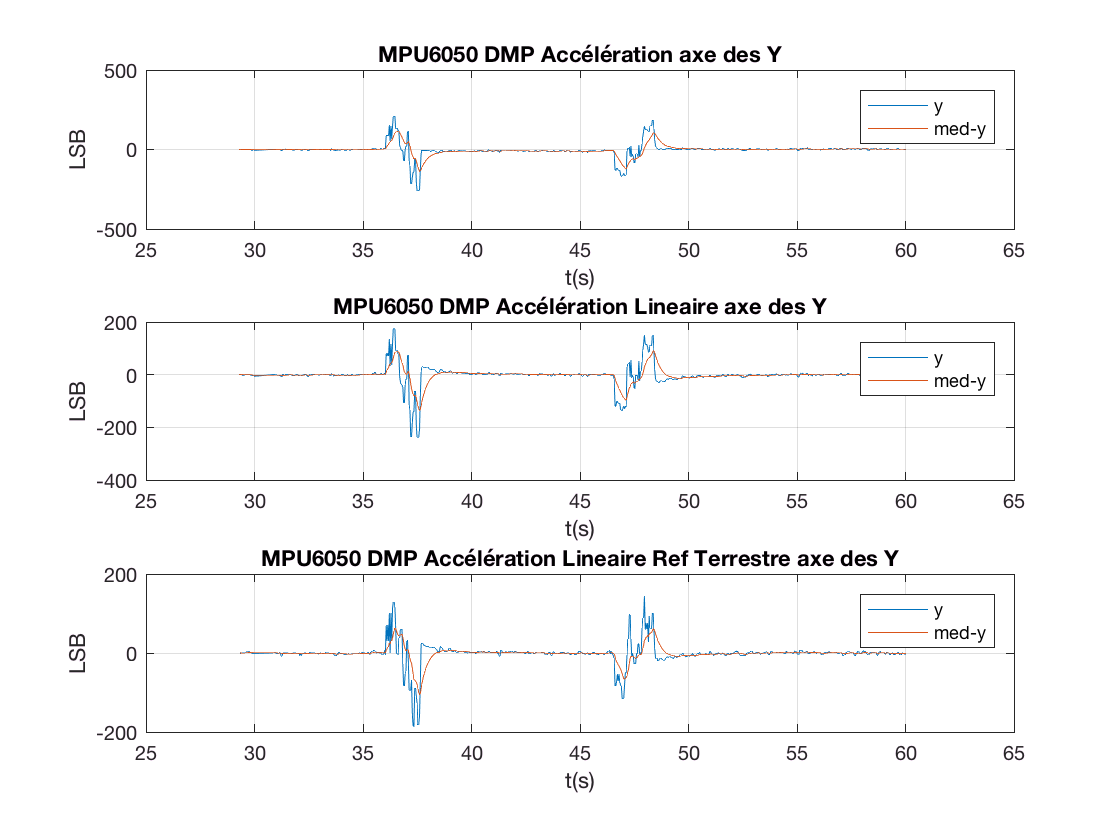

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), medfilt1(sub_accel(:,2), 3), sub_timestamp(:), EMA(medfilt1(sub_accel(:,2),3), 0.1, 0.0));
str = ['MPU6050 DMP Accélération axe des Y'];
title(ax1,str);
legend(ax1, {'y' 'med-y'});
grid(ax1, 'on');
ylabel(ax1,'LSB');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), medfilt1(sub_laccel(:,2), 3), sub_timestamp(:), EMA(medfilt1(sub_laccel(:,2),3), 0.1, 0.0));
str = ['MPU6050 DMP Accélération Lineaire axe des Y'];
title(ax2,str);
legend(ax2, {'y' 'med-y'});
grid(ax2, 'on');
ylabel(ax2,'LSB');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), medfilt1(sub_laccelw(:,2), 3), sub_timestamp(:),  EMA(medfilt1(sub_laccelw(:,2),3), 0.1, 0.0));
str = ['MPU6050 DMP Accélération Lineaire Ref Terrestre axe des Y'];
title(ax3,str);
legend(ax3, {'y' 'med-y'});
grid(ax3, 'on');
ylabel(ax3,'LSB');
xlabel(ax3,'t(s)');

## Observation de l'impact des données abérantes et de l'utilisation d'un filtre médiane afin de les éliminer ou au mieux les atténuer.

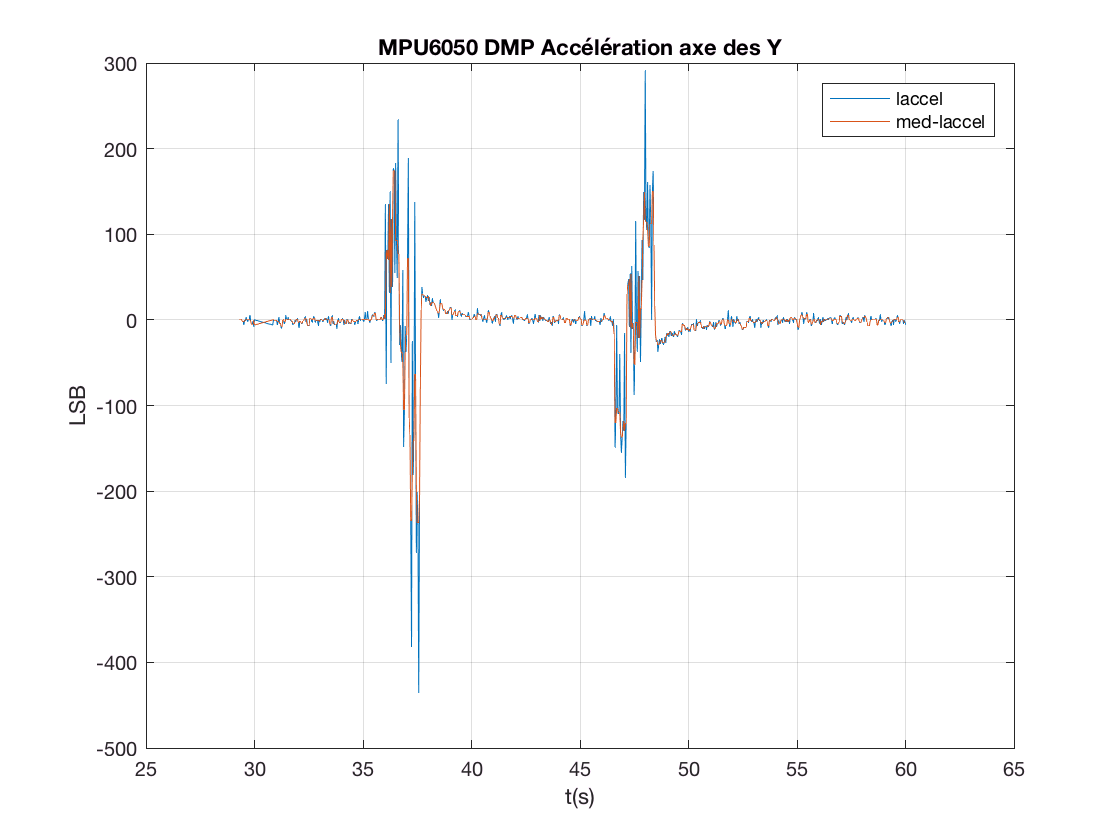

figure;
plot( sub_timestamp(:), sub_laccel(:,2), sub_timestamp(:), medfilt1(sub_laccel(:,2),3) );
title 'MPU6050 DMP Accélération axe des Y';
legend({'laccel' 'med-laccel'   });
grid 'on';
ylabel 'LSB';
xlabel 't(s)';

## Comparatif des profils des différentes 3 types d'accélération calculé par le module.

Observation: Pendant différents test, l'on a observé que l'accélération linéaire en référentiel terrestre est parfois inversé sur l'axe our bien sur le même axe mais inversé. Alors, cette valeurs d'accélération n'est pas un bon candiat pour être utilisé. À l'opposé les valeurs d'accélération brute sont impacté par la gravité et no sont pas uassi un bon candidat. Les valeurs d'accélération linéaire eux sont dépourvu de l'effet de la gravité et représente adéquatement la dirrection du module lors de son déplacement.

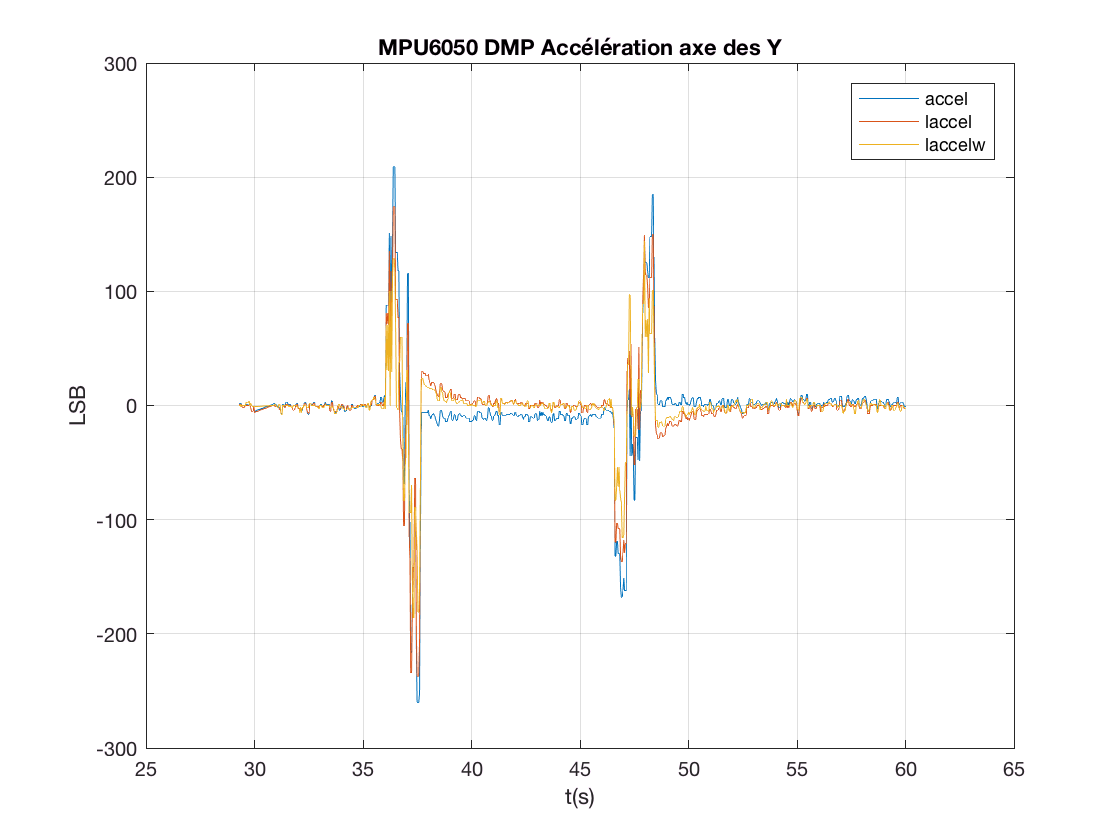

figure;
plot( sub_timestamp(:),  medfilt1(sub_accel(:,2),3), sub_timestamp(:),  medfilt1(sub_laccel(:,2),3), sub_timestamp(:),  medfilt1(sub_laccelw(:,2),3) );
title 'MPU6050 DMP Accélération axe des Y';
legend({'accel' 'laccel' 'laccelw'  });
grid 'on';
ylabel 'LSB';
xlabel 't(s)';

## Observation l'influence de la gravité sur les différents axes.

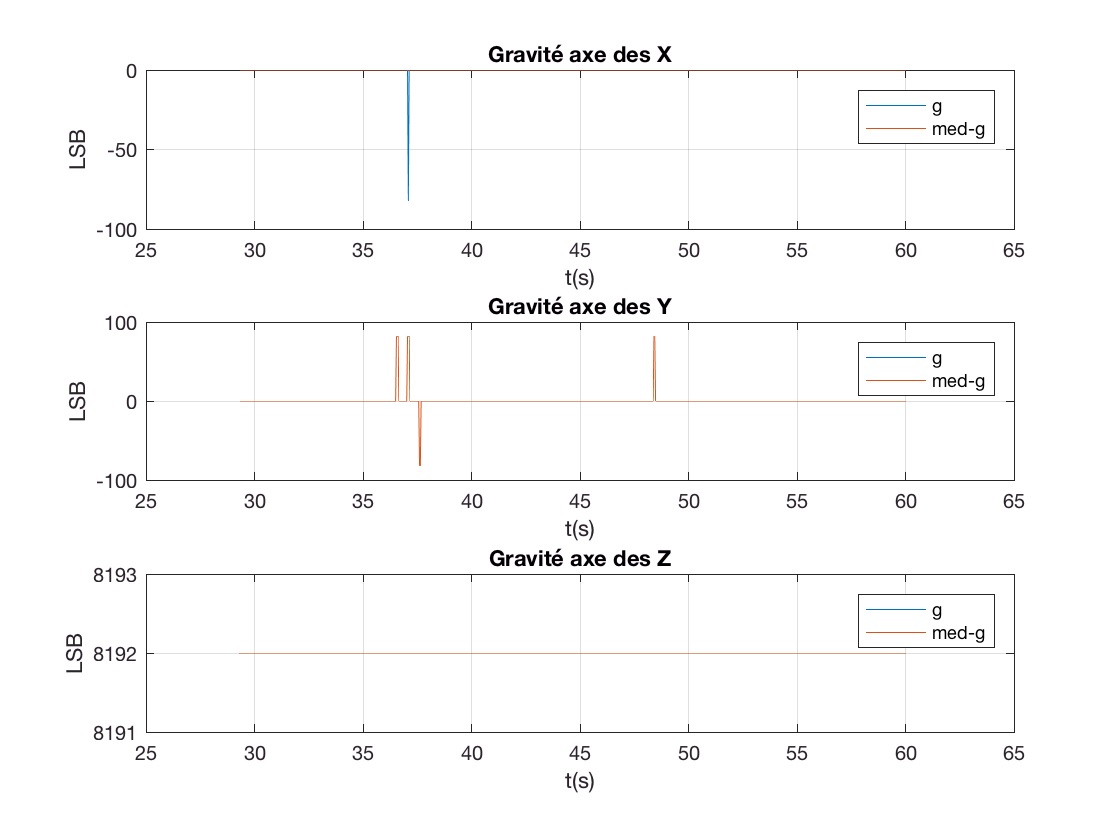


smoothedG = medfilt1(sub_g(:, :)*8192, 3);

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), sub_g(:,1)*8192 , sub_timestamp(:), smoothedG(:,1));
str = ['Gravité axe des X'];
title(ax1,str);
legend(ax1, {'g' 'med-g'});
grid(ax1, 'on');
ylabel(ax1,'LSB');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:),sub_g(:,2)*8192, sub_timestamp(:), smoothedG(:,2));
str = ['Gravité axe des Y'];
title(ax2,str);
legend(ax2, {'g' 'med-g'});
grid(ax2, 'on');
ylabel(ax2,'LSB');
xlabel(ax2,'t(s)');
plot(ax3,sub_timestamp(:),sub_g(:,3)*8192, sub_timestamp(:), smoothedG(:,3));
str = ['Gravité axe des Z'];
title(ax3,str);
legend(ax3, {'g' 'med-g'});
grid(ax3, 'on');
ylabel(ax3,'LSB');
xlabel(ax3,'t(s)');

## Affichage des valeurs du gyroscope en  ${º/s}$.

Grâce aux observation de la direction du module calculer à partir du magnétomètre, de l'angle d'Euler$\psi$ et de l'axe des Z du gyroscope, il est facile d'observé que pendant les déplacements, la direction du module varie, ce qui explique l'axe des X de l'accéléromètre soit aussi engagé.

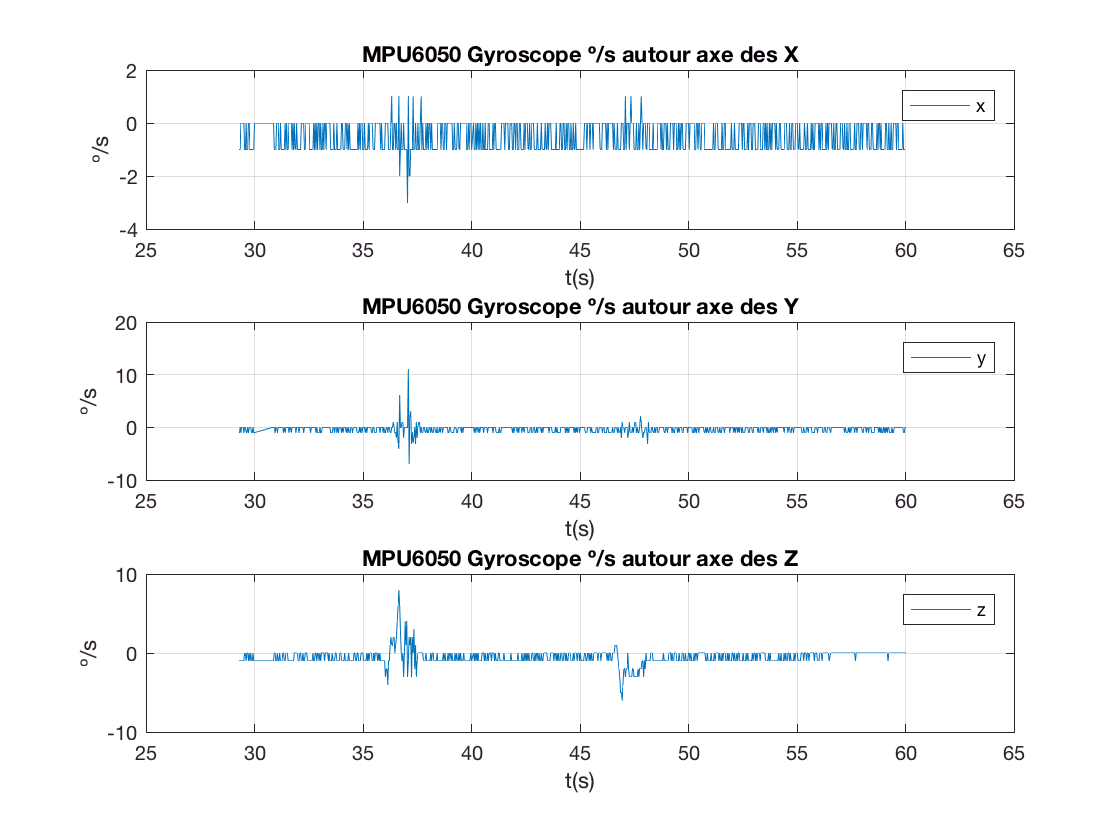

scaledGyro = sub_rawGyro(:, 1:3);
figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), scaledGyro(:,1));
title(ax1,'MPU6050 Gyroscope º/s autour axe des X');
legend(ax1, 'x');
grid(ax1, 'on');
ylabel(ax1,'º/s');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), scaledGyro(:,2));
title(ax2,'MPU6050 Gyroscope º/s autour axe des Y');
legend(ax2, 'y');
grid(ax2, 'on');
ylabel(ax2,'º/s');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), scaledGyro(:,3));
title(ax3,'MPU6050 Gyroscope º/s autour axe des Z');
legend(ax3, 'z');
grid(ax3, 'on');
ylabel(ax3,'º/s');
xlabel(ax3,'t(s)');

## Affichage des valeurs du magétomètre en  $G$.

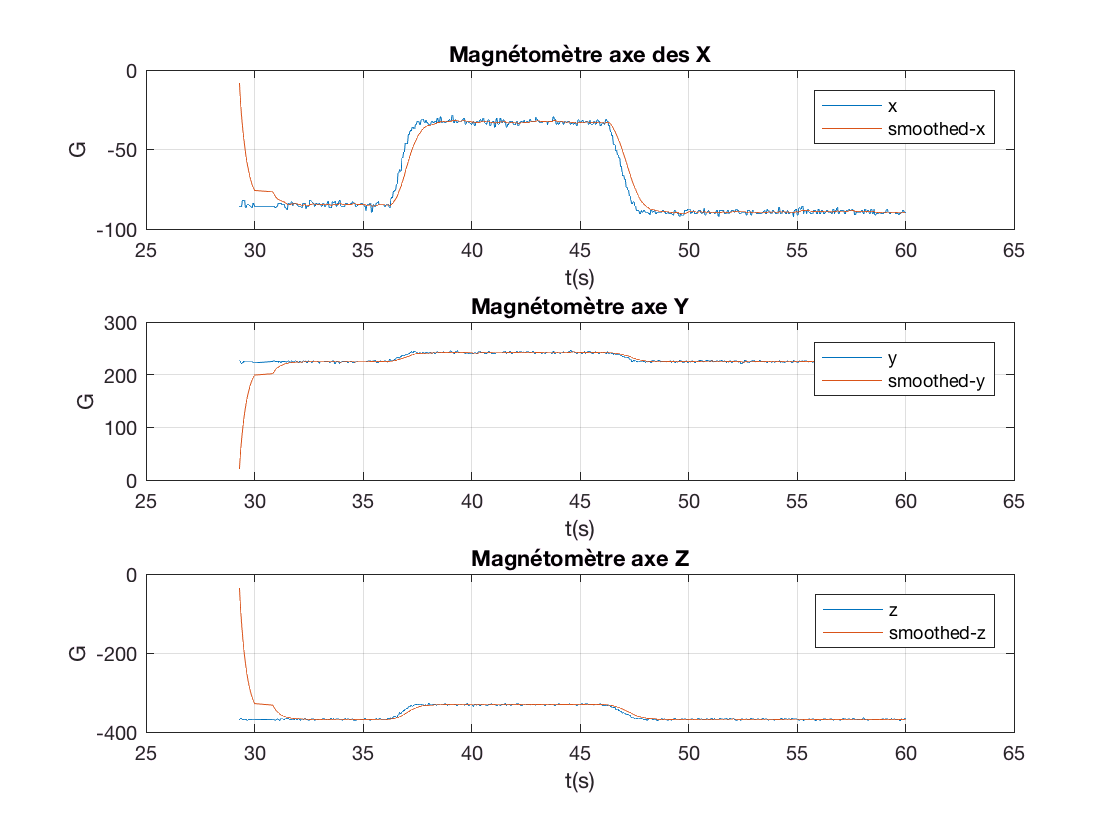

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), sub_rawMag(:,1), sub_timestamp(:),EMA(sub_rawMag(:,1),0.1, 0));
title(ax1,'Magnétomètre axe des X');
legend(ax1, {'x','smoothed-x'});
grid(ax1, 'on');
ylabel(ax1,'G');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), sub_rawMag(:,2), sub_timestamp(:),EMA(sub_rawMag(:,2),0.1,0));
title(ax2,'Magnétomètre axe Y');
legend(ax2, {'y','smoothed-y'});
grid(ax2, 'on');
ylabel(ax2,'G');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), sub_rawMag(:,3), sub_timestamp(:),EMA(sub_rawMag(:,3),0.1,0));
title(ax3,'Magnétomètre axe Z');
legend(ax3, {'z','smoothed-z'});
grid(ax3, 'on');
ylabel(ax3,'G');
xlabel(ax3,'t(s)');

## Affichage de la direction en º, à partir des valeurs du magétomètre.

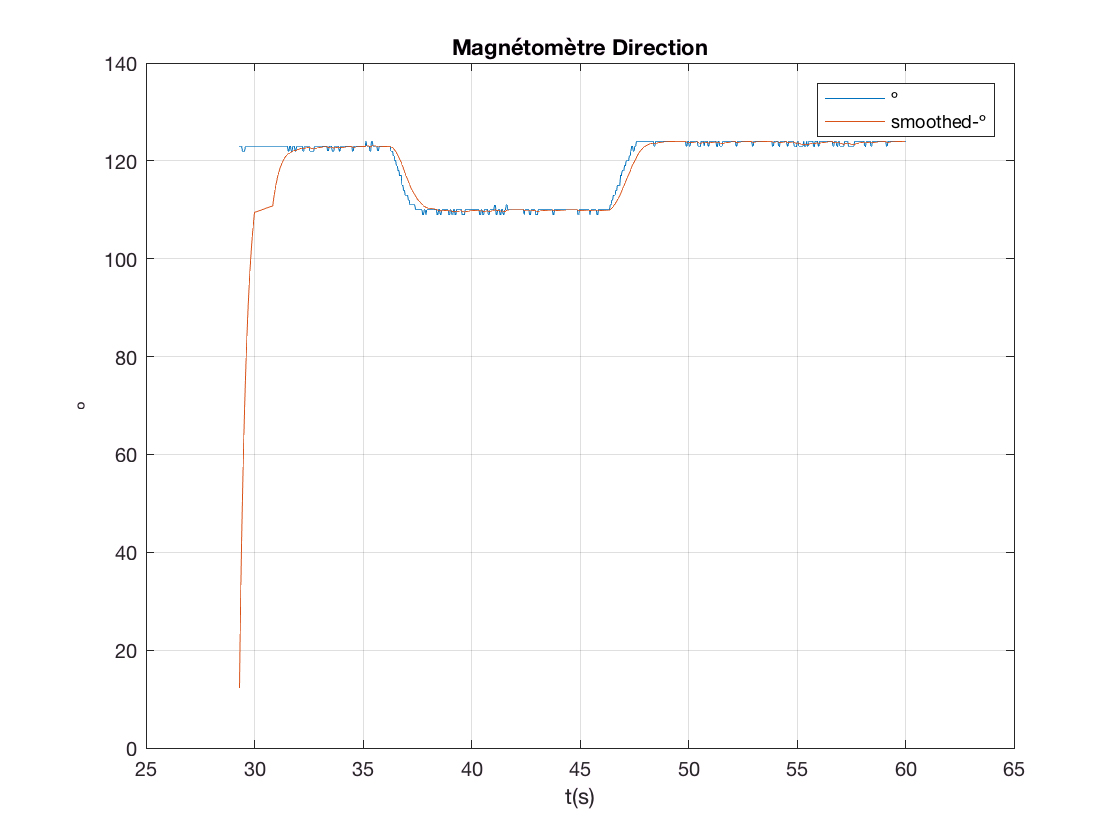

figure
plot(sub_heading(:,2),sub_heading(:,1), sub_heading(:,2), EMA(sub_heading(:,1),0.1, 0));
title 'Magnétomètre Direction';
legend({'º', 'smoothed-º'});
grid 'on';
ylabel 'º';
xlabel 't(s)';

## Affichage des angles d'Euleur à partir des quaternions.

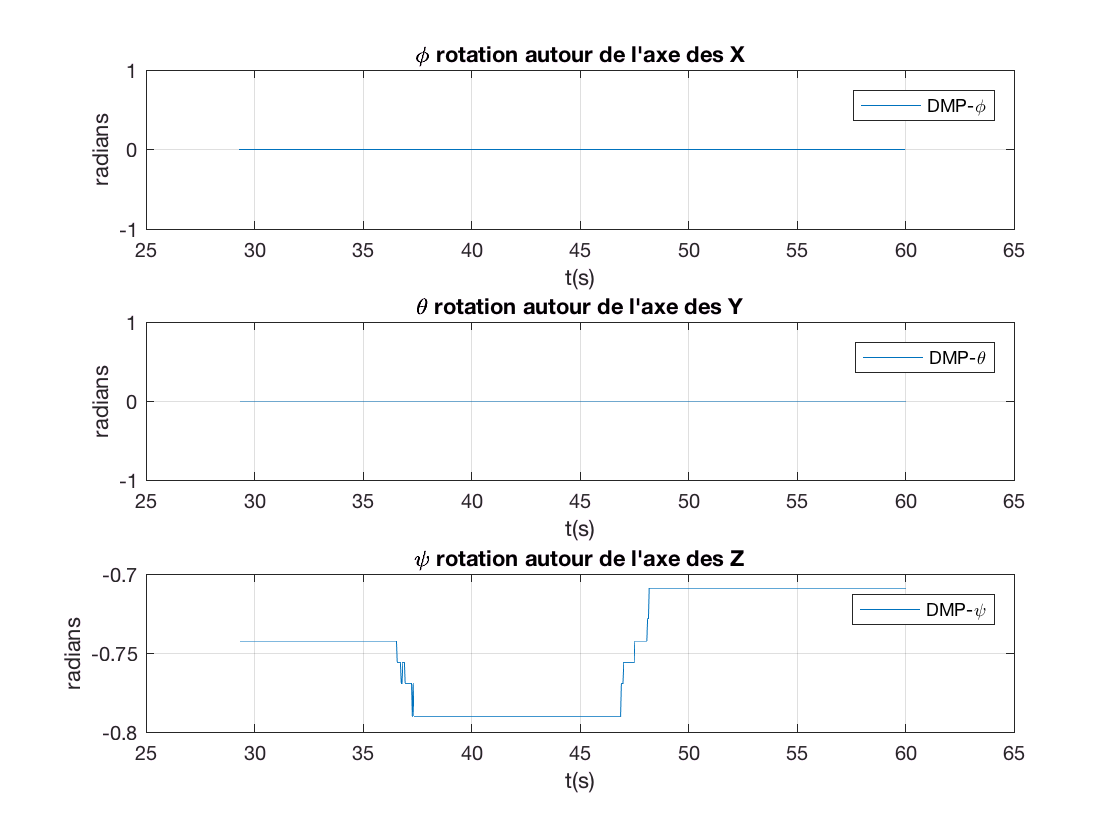

addpath('quaternion_library'); 
euler2 = zeros(length(sub_Q), 3);
for i = 1:length(sub_Q)
    euler2(i, :) = quatern2euler(sub_Q(i,1:4));
end

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);

plot(ax1,  sub_timestamp(:), euler2(:,1));
title(ax1,'\phi rotation autour de l''axe des X');
legend(ax1, {'DMP-\phi'});
grid(ax1, 'on');
ylabel(ax1,'radians');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), euler2(:,2));
title(ax2,'\theta rotation autour de l''axe des Y');
legend(ax2, { 'DMP-\theta'});
grid(ax2, 'on');
ylabel(ax2,'radians');
xlabel(ax2,'t(s)');

plot(ax3, sub_timestamp(:), euler2(:,3));
title(ax3,'\psi rotation autour de l''axe des Z');
legend(ax3, {'DMP-\psi'});
grid(ax3, 'on');
ylabel(ax3,'radians');
xlabel(ax3,'t(s)');

# Calcul du déplacement du module à partir de seulement les données d'accélération

## Option 1 : Application d'un filtre médiane seulement

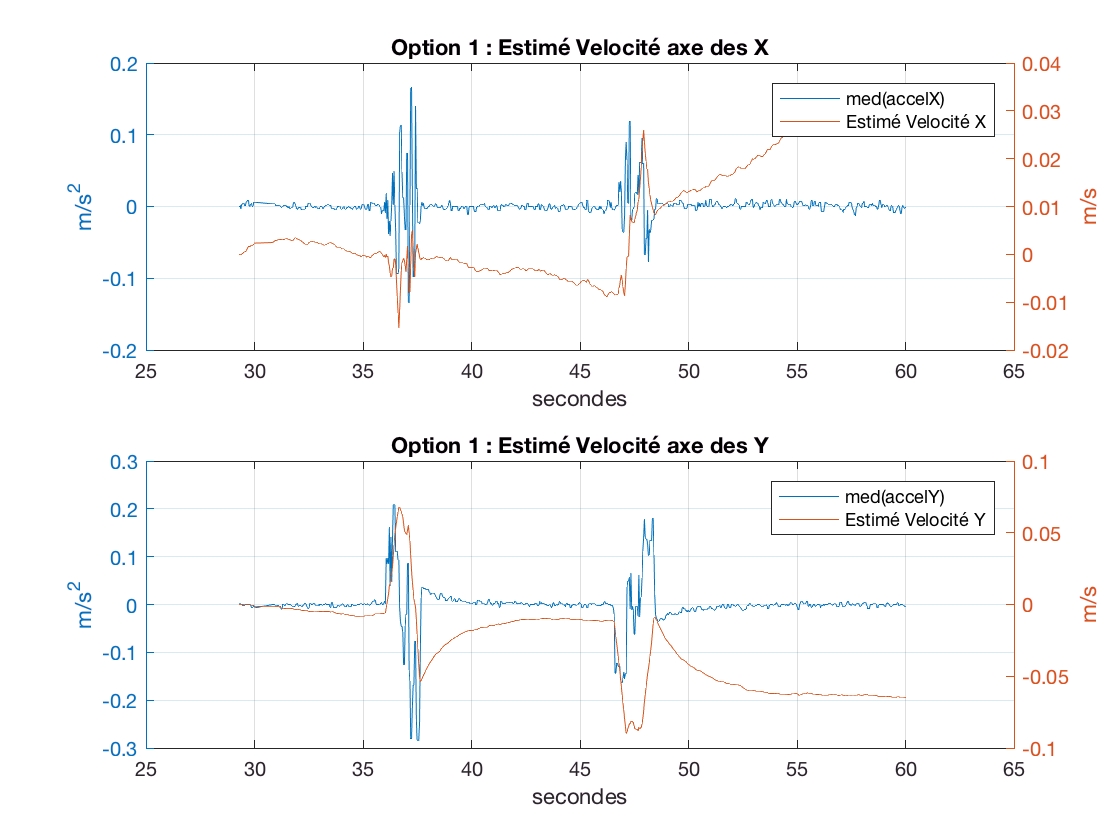

%application d'un filtre médiane sur les valeurs de l'accéléromètre afin d'éliminer les données abérantes.
medfiltAccel = medfilt1(sub_laccel, 3);

%Les valeurs brutes de l'accéléromètre ont été acquise avec un facteur de 8192 LSB/g. (8192 in standard DMP FIFO packet)
scaledAccel = medfiltAccel / 8192.0 * 9.81; 

%Calcule du déplacement du module à partir des valeurs d'accélération
lucVel = zeros(length(scaledAccel), 2);
lucPos = zeros(length(scaledAccel), 2);
for i = 1:length(scaledAccel)
    %X
    if i ~= 1
        lucVel(i, 1) = lucVel(i-1, 1) + avgDt * scaledAccel(i,1);
    else
        lucVel(i, 1) = avgDt * scaledAccel(i,1);
    end
        
    if i ~= 1
        lucPos(i, 1) = lucPos(i-1, 1) + avgDt * lucVel(i, 1);
    else
        lucPos(i, 1) = avgDt * lucVel(i, 1);
    end


    %Y
    if i ~= 1
        lucVel(i, 2) = lucVel(i-1, 2) + avgDt * scaledAccel(i,2);
    else
        lucVel(i, 2) = avgDt * scaledAccel(i,2);
    end
        
    if i ~= 1
        lucPos(i, 2) = lucPos(i-1, 2) + avgDt * lucVel(i, 2);
    else
        lucPos(i, 2) = avgDt * lucVel(i, 2);
    end

end

figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), scaledAccel(:, 1) );
title(ax1,'Option 1 : Estimé Velocité axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s^2');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
ylabel(ax1,'m/s');
legend(ax1, {'med(accelX)', 'Estimé Velocité X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), scaledAccel(:, 2));
title(ax2,'Option 1 : Estimé Velocité axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s^2');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
ylabel(ax2,'m/s');
legend(ax2, {'med(accelY)', 'Estimé Velocité Y'});
grid(ax2, 'on');

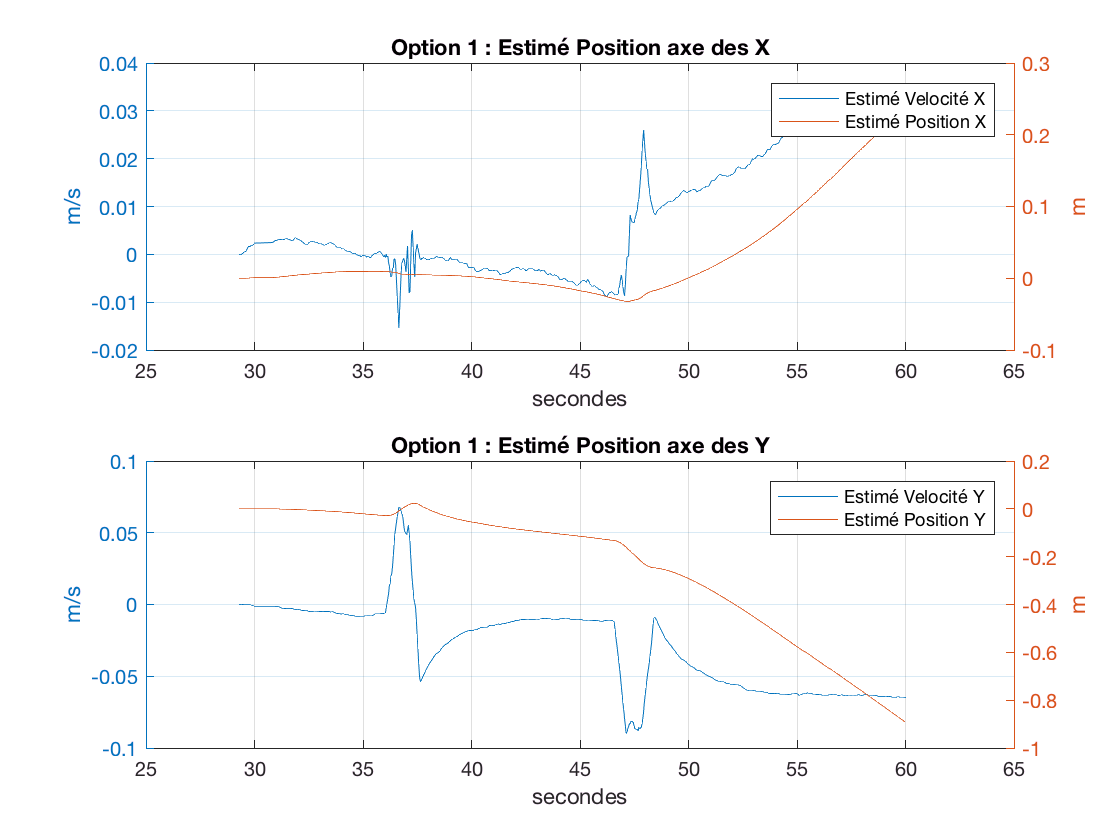


figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
title(ax1,'Option 1 : Estimé Position axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucPos(:, 1) );
ylabel(ax1,'m');
legend(ax1, {'Estimé Velocité X', 'Estimé Position X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
title(ax2,'Option 1 : Estimé Position axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucPos(:, 2) );
ylabel(ax2,'m');
legend(ax2, {'Estimé Velocité Y', 'Estimé Position Y'});
grid(ax2, 'on');

## Option 2 : Application du filtre médiane + cutoff

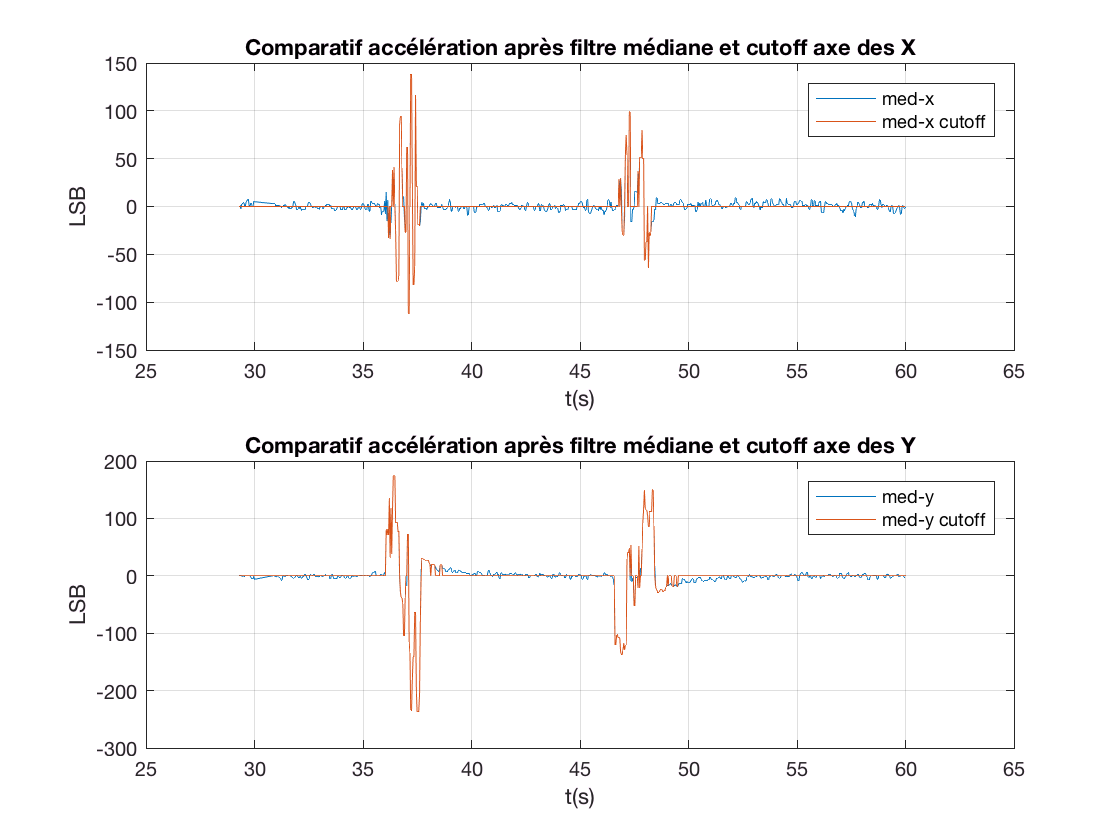

%application d'un filtre médiane sur les valeurs de l'accéléromètre afin d'éliminer les données abérantes.
medfiltAccel = medfilt1(sub_laccel, 3);

%De notre analyse sans mouvement, nous avons observé que malgré l'utilisation du DMP qui minimize le bruit, 
%il y reste quand même un peut de bruit entre -17 LSB et 17 LSB. Nous allons alors forcé toute accélération 
%ce retrouvant entre ces valeurs a zéro.
cutoff = 17 ;%(cutoff-value)
for i = 1:length(sub_laccel)
    if medfiltAccel(i,1) >= -cutoff && medfiltAccel(i,1) <= cutoff
        medfiltAccel(i,1) = 0.0;
    end
    
    if medfiltAccel(i,2) >= -cutoff && medfiltAccel(i,2) <= cutoff
        medfiltAccel(i,2) = 0.0;
    end
end


figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);
plot(ax1, sub_timestamp(:), medfilt1(sub_laccel(:,1), 3), sub_timestamp(:), medfiltAccel(:,1));
title(ax1,'Comparatif accélération après filtre médiane et cutoff axe des X');
legend(ax1, {'med-x' 'med-x cutoff' });
grid(ax1, 'on');
ylabel(ax1,'LSB');
xlabel(ax1,'t(s)');

plot(ax2, sub_timestamp(:), medfilt1(sub_laccel(:,2), 3), sub_timestamp(:), medfiltAccel(:,2));
title(ax2,'Comparatif accélération après filtre médiane et cutoff axe des Y');
legend(ax2, {'med-y' 'med-y cutoff' });
grid(ax2, 'on');
ylabel(ax2,'LSB');
xlabel(ax2,'t(s)');

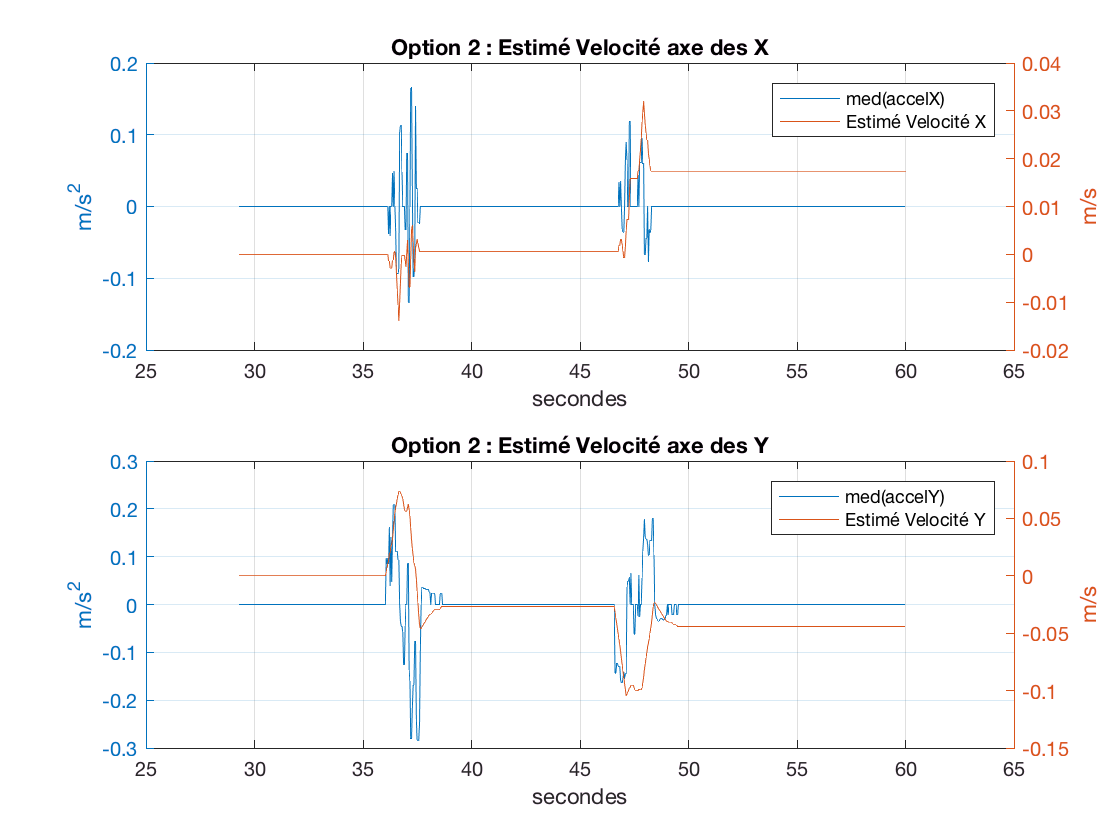



%Les valeurs brutes de l'accéléromètre ont été acquise avec un facteur de 8192 LSB/g. (8192 in standard DMP FIFO packet)
scaledAccel = medfiltAccel / 8192.0 * 9.81; 

%Calcule du déplacement du module à partir des valeurs d'accélération
lucVel = zeros(length(scaledAccel), 2);
lucPos = zeros(length(scaledAccel), 2);
for i = 1:length(scaledAccel)
    %X
    if i ~= 1
        lucVel(i, 1) = lucVel(i-1, 1) + avgDt * scaledAccel(i,1);
    else
        lucVel(i, 1) = avgDt * scaledAccel(i,1);
    end
        
    if i ~= 1
        lucPos(i, 1) = lucPos(i-1, 1) + avgDt * lucVel(i, 1);
    else
        lucPos(i, 1) = avgDt * lucVel(i, 1);
    end


    %Y
    if i ~= 1
        lucVel(i, 2) = lucVel(i-1, 2) + avgDt * scaledAccel(i,2);
    else
        lucVel(i, 2) = avgDt * scaledAccel(i,2);
    end
        
    if i ~= 1
        lucPos(i, 2) = lucPos(i-1, 2) + avgDt * lucVel(i, 2);
    else
        lucPos(i, 2) = avgDt * lucVel(i, 2);
    end

end

figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), scaledAccel(:, 1) );
title(ax1,'Option 2 : Estimé Velocité axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s^2');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
ylabel(ax1,'m/s');
legend(ax1, {'med(accelX)', 'Estimé Velocité X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), scaledAccel(:, 2));
title(ax2,'Option 2 : Estimé Velocité axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s^2');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
ylabel(ax2,'m/s');
legend(ax2, {'med(accelY)', 'Estimé Velocité Y'});
grid(ax2, 'on');

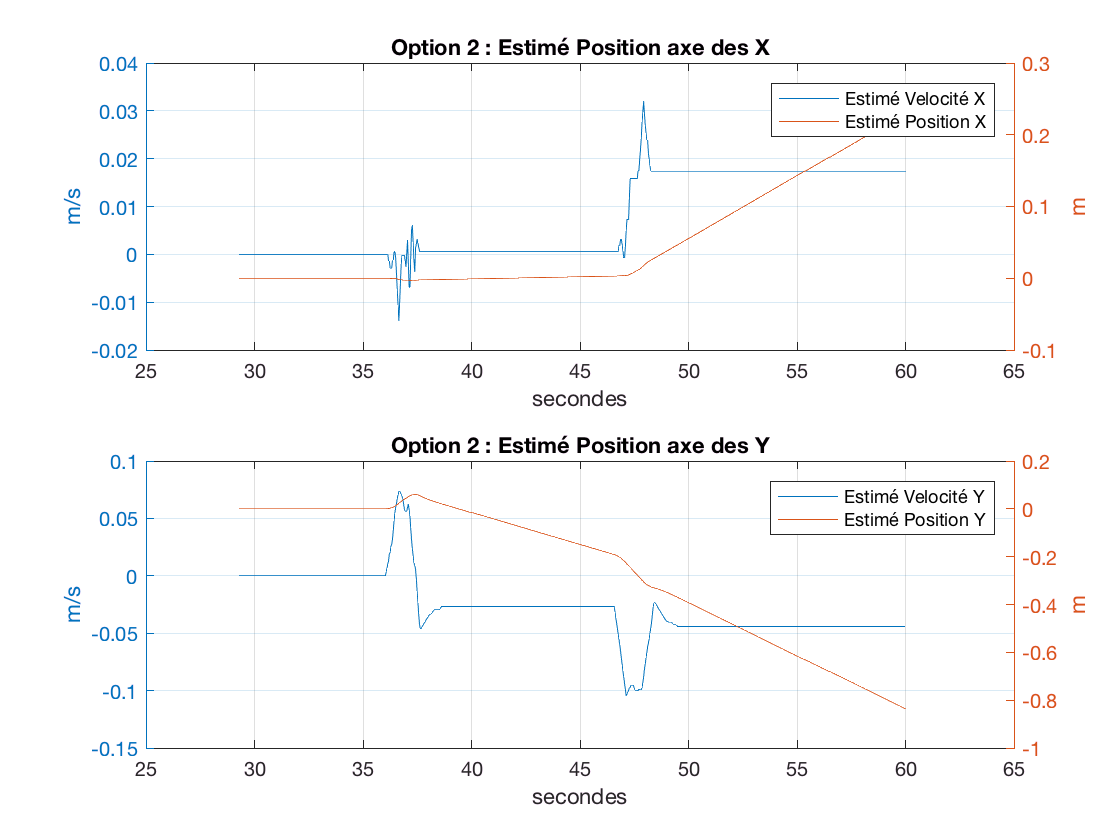


figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
title(ax1,'Option 2 : Estimé Position axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucPos(:, 1) );
ylabel(ax1,'m');
legend(ax1, {'Estimé Velocité X', 'Estimé Position X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
title(ax2,'Option 2 : Estimé Position axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucPos(:, 2) );
ylabel(ax2,'m');
legend(ax2, {'Estimé Velocité Y', 'Estimé Position Y'});
grid(ax2, 'on');

## Option 3 : Application du filtre médiane + cutoff + smoothing

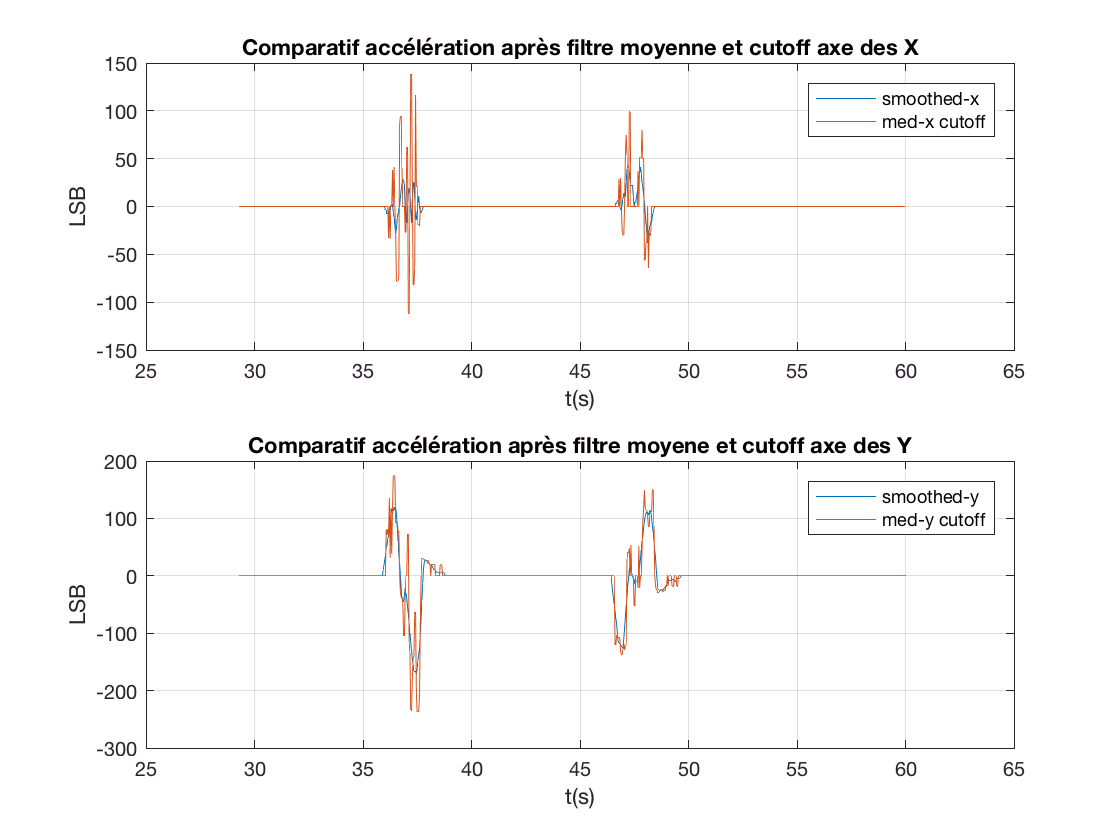

%application d'un filtre médiane sur les valeurs de l'accéléromètre afin d'éliminer les données abérantes.
medfiltAccel = medfilt1(sub_laccel, 3);

%De notre analyse sans mouvement, nous avons observé que malgré l'utilisation du DMP qui minimize le bruit, 
%il y reste quand même un peut de bruit entre -17 LSB et 17 LSB. Nous allons alors forcé toute accélération 
%ce retrouvant entre ces valeurs a zéro.
cutoff = 17 ;%(cutoff-value)
for i = 1:length(sub_laccel)
    if medfiltAccel(i,1) >= -cutoff && medfiltAccel(i,1) <= cutoff
        medfiltAccel(i,1) = 0.0;
    end
    
    if medfiltAccel(i,2) >= -cutoff && medfiltAccel(i,2) <= cutoff
        medfiltAccel(i,2) = 0.0;
    end
end

%Nous allons ensuite appliquer un filtre de lissage afin d'avoir une moyenne courante.
%smoothedAccel = EMA(medfiltAccel, 0.9, 0.0);
smoothedAccel = sgolayfilt(medfiltAccel, 1, 9);

figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);
plot(ax1, sub_timestamp(:), smoothedAccel(:,1), sub_timestamp(:), medfiltAccel(:,1));
title(ax1,'Comparatif accélération après filtre moyenne et cutoff axe des X');
legend(ax1, {'smoothed-x' 'med-x cutoff' });
grid(ax1, 'on');
ylabel(ax1,'LSB');
xlabel(ax1,'t(s)');

plot(ax2, sub_timestamp(:), smoothedAccel(:,2), sub_timestamp(:), medfiltAccel(:,2));
title(ax2,'Comparatif accélération après filtre moyene et cutoff axe des Y');
legend(ax2, {'smoothed-y' 'med-y cutoff' });
grid(ax2, 'on');
ylabel(ax2,'LSB');
xlabel(ax2,'t(s)');

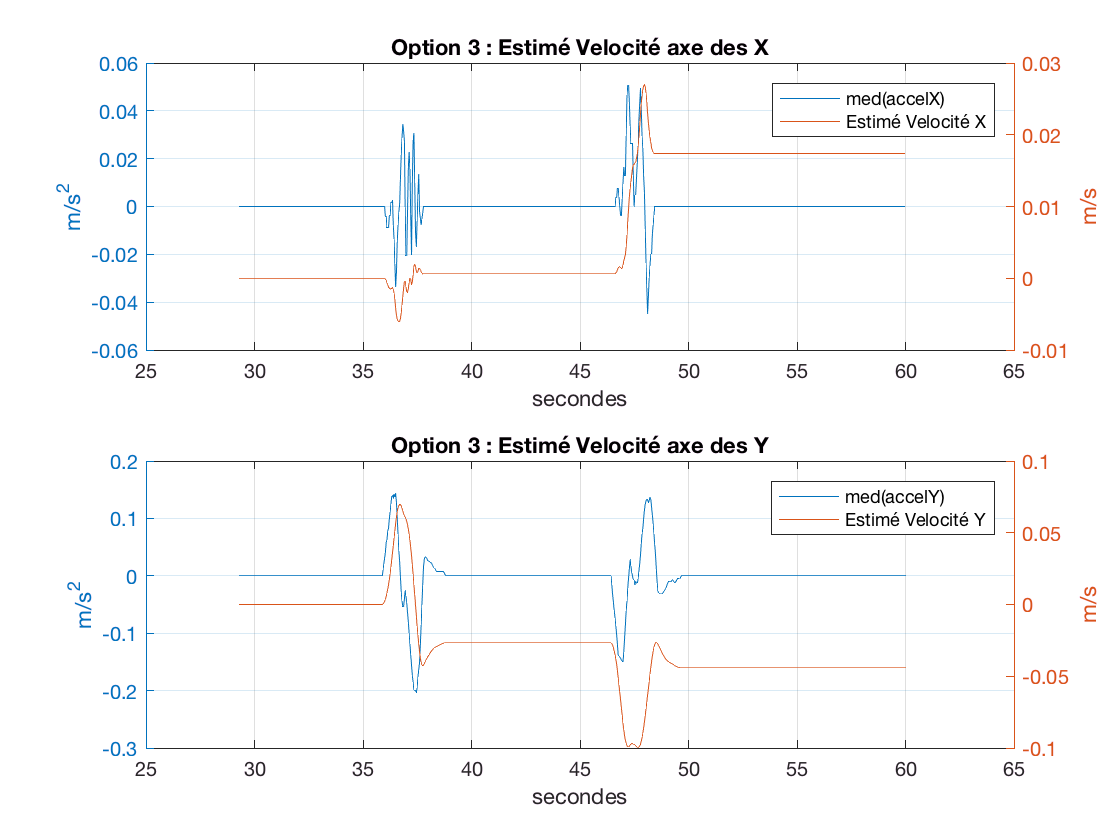


%Les valeurs brutes de l'accéléromètre ont été acquise avec un facteur de 8192 LSB/g. (8192 in standard DMP FIFO packet)
scaledAccel = smoothedAccel / 8192.0 * 9.81; 

%Calcule du déplacement du module à partir des valeurs d'accélération
lucVel = zeros(length(scaledAccel), 2);
lucPos = zeros(length(scaledAccel), 2);
for i = 1:length(scaledAccel)
    %X
    if i ~= 1
        lucVel(i, 1) = lucVel(i-1, 1) + avgDt * scaledAccel(i,1);
    else
        lucVel(i, 1) = avgDt * scaledAccel(i,1);
    end
        
    if i ~= 1
        lucPos(i, 1) = lucPos(i-1, 1) + avgDt * lucVel(i, 1);
    else
        lucPos(i, 1) = avgDt * lucVel(i, 1);
    end


    %Y
    if i ~= 1
        lucVel(i, 2) = lucVel(i-1, 2) + avgDt * scaledAccel(i,2);
    else
        lucVel(i, 2) = avgDt * scaledAccel(i,2);
    end
        
    if i ~= 1
        lucPos(i, 2) = lucPos(i-1, 2) + avgDt * lucVel(i, 2);
    else
        lucPos(i, 2) = avgDt * lucVel(i, 2);
    end

end

figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), scaledAccel(:, 1) );
title(ax1,'Option 3 : Estimé Velocité axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s^2');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
ylabel(ax1,'m/s');
legend(ax1, {'med(accelX)', 'Estimé Velocité X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), scaledAccel(:, 2));
title(ax2,'Option 3 : Estimé Velocité axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s^2');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
ylabel(ax2,'m/s');
legend(ax2, {'med(accelY)', 'Estimé Velocité Y'});
grid(ax2, 'on');

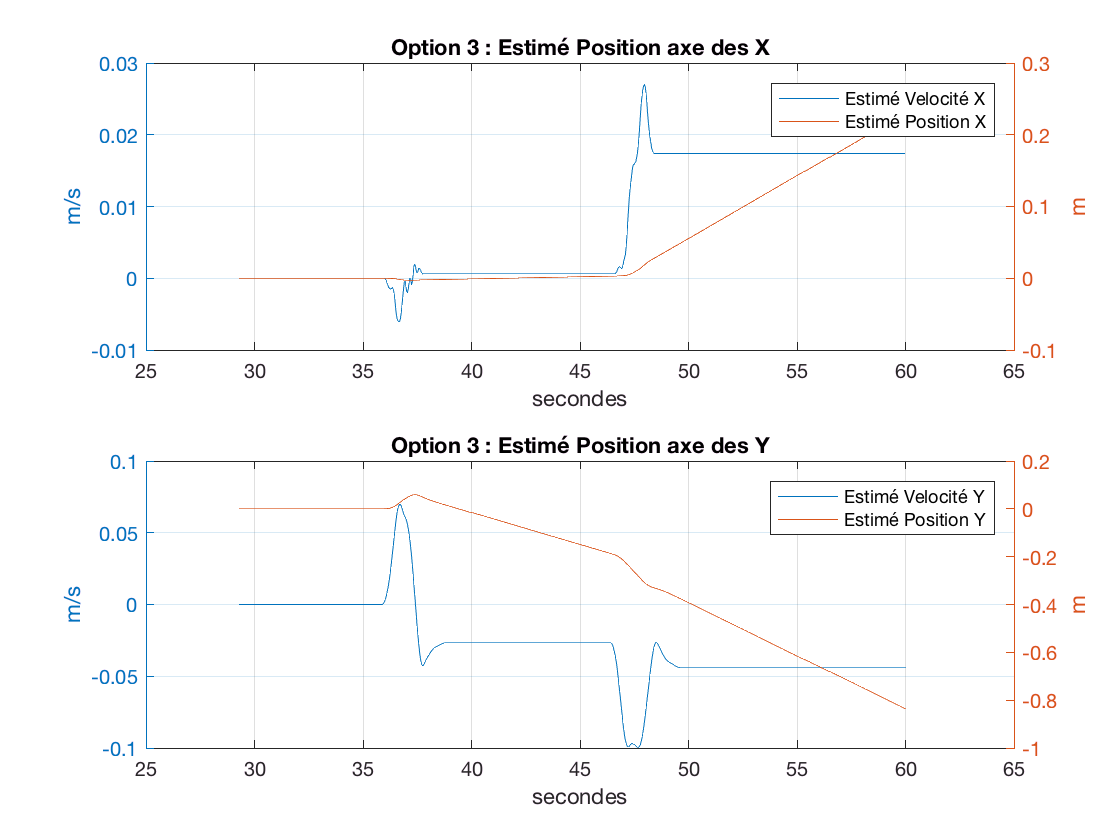


figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
title(ax1,'Option 3 : Estimé Position axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucPos(:, 1) );
ylabel(ax1,'m');
legend(ax1, {'Estimé Velocité X', 'Estimé Position X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
title(ax2,'Option 3 : Estimé Position axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucPos(:, 2) );
ylabel(ax2,'m');
legend(ax2, {'Estimé Velocité Y', 'Estimé Position Y'});
grid(ax2, 'on');

## Option 4 : Application du filtre médiane + cutoff + smoothing + cutoff

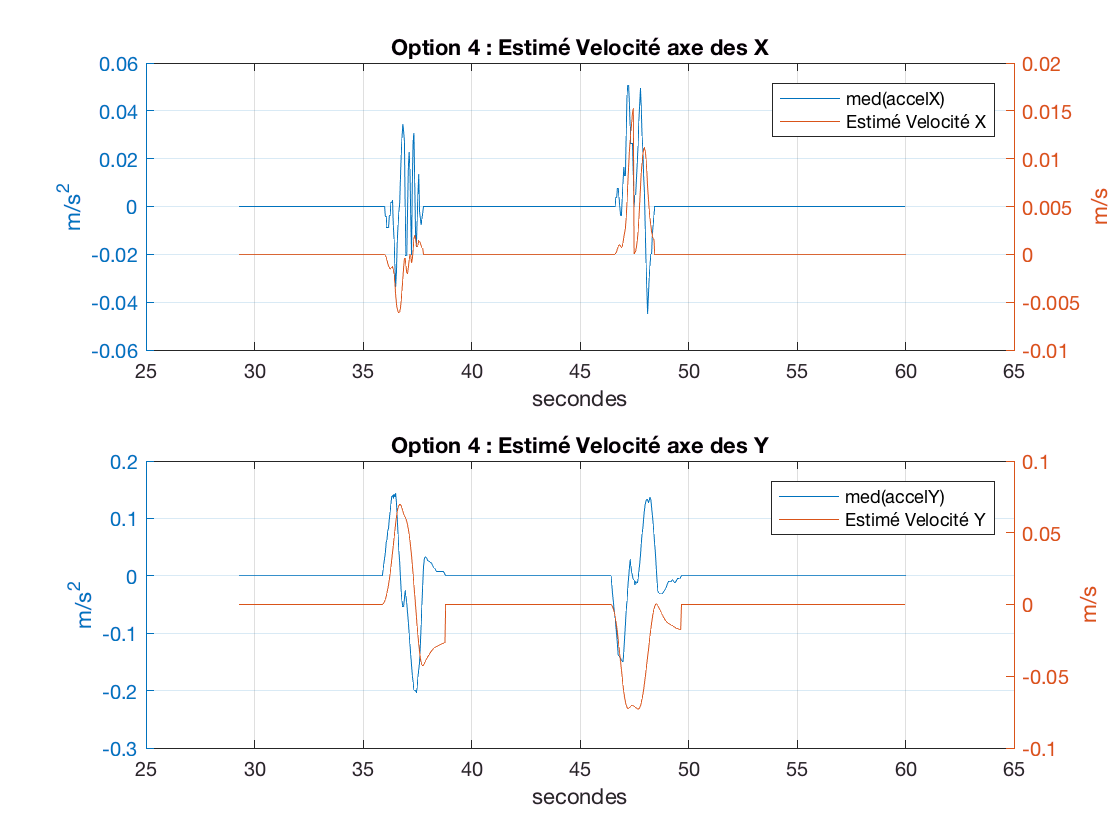

%application d'un filtre médiane sur les valeurs de l'accéléromètre afin d'éliminer les données abérantes.
medfiltAccel = medfilt1(sub_laccel, 3);

%De notre analyse sans mouvement, nous avons observé que malgré l'utilisation du DMP qui minimize le bruit, 
%il y reste quand même un peut de bruit entre -17 LSB et 17 LSB. Nous allons alors forcé toute accélération 
%ce retrouvant entre ces valeurs a zéro.
cutoff = 17 ;%(cutoff-value)
for i = 1:length(sub_laccel)
    if medfiltAccel(i,1) >= -cutoff && medfiltAccel(i,1) <= cutoff
        medfiltAccel(i,1) = 0.0;
    end
    
    if medfiltAccel(i,2) >= -cutoff && medfiltAccel(i,2) <= cutoff
        medfiltAccel(i,2) = 0.0;
    end
end

%Nous allons ensuite appliquer un filtre de lissage afin d'avoir une moyenne courante.
%smoothedAccel = EMA(medfiltAccel, 0.9, 0.0);
smoothedAccel = sgolayfilt(medfiltAccel, 1, 9);

%Les valeurs brutes de l'accéléromètre ont été acquise avec un facteur de 8192 LSB/g. (8192 in standard DMP FIFO packet)
scaledAccel = smoothedAccel / 8192.0 * 9.81; 

%Calcule du déplacement du module à partir des valeurs d'accélération avec option de mis a zéro 
% des valeurs de vélocité lorsque la valeurs d'accélération est proche de zéro.
lucVel = zeros(length(scaledAccel), 2);
lucPos = zeros(length(scaledAccel), 2);
for i = 1:length(scaledAccel)
    %X
    if scaledAccel(i,1) < 0.0001 && scaledAccel(i,1) > -0.0001
        lucVel(i, 1) = 0.0;
    elseif i ~= 1
        lucVel(i, 1) = lucVel(i-1, 1) + avgDt * scaledAccel(i,1);
    else
        lucVel(i, 1) = avgDt * scaledAccel(i,1);
    end
        
    if i ~= 1
        lucPos(i, 1) = lucPos(i-1, 1) + avgDt * lucVel(i, 1);
    else
        lucPos(i, 1) = avgDt * lucVel(i, 1);
    end


    %Y
    if scaledAccel(i,2) < 0.0001 && scaledAccel(i,2) > -0.0001 
        lucVel(i, 2) = 0.0;
    elseif i ~= 1
        lucVel(i, 2) = lucVel(i-1, 2) + avgDt * scaledAccel(i,2);
    else
        lucVel(i, 2) = avgDt * scaledAccel(i,2);
    end
        
    if i ~= 1
        lucPos(i, 2) = lucPos(i-1, 2) + avgDt * lucVel(i, 2);
    else
        lucPos(i, 2) = avgDt * lucVel(i, 2);
    end

end


figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), scaledAccel(:, 1) );
title(ax1,'Option 4 : Estimé Velocité axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s^2');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
ylabel(ax1,'m/s');
legend(ax1, {'med(accelX)', 'Estimé Velocité X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), scaledAccel(:, 2));
title(ax2,'Option 4 : Estimé Velocité axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s^2');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
ylabel(ax2,'m/s');
legend(ax2, {'med(accelY)', 'Estimé Velocité Y'});
grid(ax2, 'on');

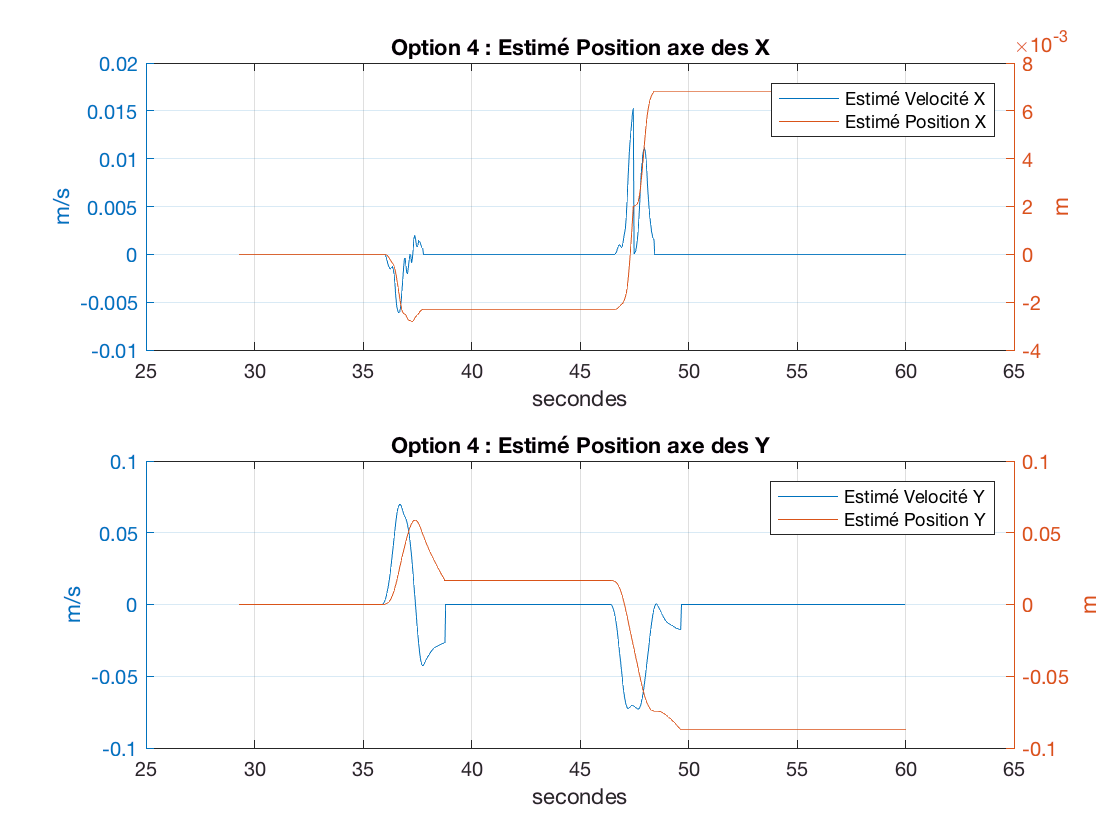


figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

yyaxis(ax1,'left');
plot(ax1,sub_timestamp(:), lucVel(:, 1));
title(ax1,'Option 4 : Estimé Position axe des X');
xlabel(ax1,'secondes');
ylabel(ax1,'m/s');

yyaxis(ax1,'right');
plot(ax1,sub_timestamp(:), lucPos(:, 1) );
ylabel(ax1,'m');
legend(ax1, {'Estimé Velocité X', 'Estimé Position X'});
grid(ax1, 'on');

yyaxis(ax2,'left');
plot(ax2,sub_timestamp(:), lucVel(:, 2));
title(ax2,'Option 4 : Estimé Position axe des Y');
xlabel(ax2,'secondes');
ylabel(ax2,'m/s');

yyaxis(ax2,'right');
plot(ax2,sub_timestamp(:), lucPos(:, 2) );
ylabel(ax2,'m');
legend(ax2, {'Estimé Velocité Y', 'Estimé Position Y'});
grid(ax2, 'on');